# Homework 6 (Solutions)

Math 3607, Spring 2022

Tae Eun Kim

clear

## Problem 1 (FLOP counting; FNC 2.5.5)

(a) Consider the following code.

For iteration of the for-loop, 3 flops are needed.

- 1 multiplication to compute `xpow*x;`

- 1 addition and 1 multiplication to compute `y+c(i)*xpow`.

Since the loop body repeats $(n-1)$ times as $i$ iterates over $\mathbb{N}[2,n]$, the code overall takes $3(n-1)$ flops, which is asymptotic to $3n$ flops as $n \to \infty$. 

(b) The code below is known as the Horner's method.

 For each iteration of the for-loop, only 2 flops are required.

- 1 addition and 1 multiplication to compute `y*x + c(j)`.

Since the loop body repeats $(n-1)$ times as $j$ iterates over $\mathbb{N}[1,n-1]$ (backward), the code takes $2(n-1)$ flops, which is asymptotic to $2n$ flops as $n \to \infty$.

## Problem 2 (Matrix norms)

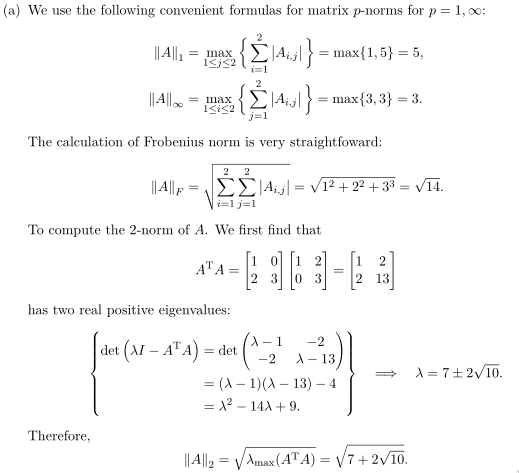

## Problem 3 (Matrix multiplication: LM 12.5--3)

In what follows, $\mathbf{a}_j \in \mathbb{R}^m$ denotes the $j$th column of $A$. 

(a) $\mathbf{r} \mathbf{w}^{\rm T}$ is an $n \times n$ matrix whose $i$th row is 

$\displaystyle r_i \mathbf{w}^{\rm T} = [ r_i w_1,\; r_i w_2,\; \ldots,\;r_i w_n] \in \mathbb{R}^{1 \times n}$.

(b) $\mathbf{b}^{\rm T} A$ is a row vector with $n$ element whose $j$th element is 

$\displaystyle \mathbf{b}^{\rm T} \mathbf{a}_j = \sum_{i=1}^{m} b_i a_{ij}$.

(c) $C$ is an $m \times p$ matrix whose $(i,j)$-entry is given by

$\displaystyle c_{i,j} = \sum_{k=1}^{n} a_{i,k} b_{k,j}$.

(d) $D$ is a $p \times m$ matrix whose $(i,j)$-entry is given by

$\displaystyle d_{i,j} = \sum_{k=1}^{n} b_{k,i} a_{j,k}$.

(e) Let $E = C^{\rm T}$. Then $E$ is a $p\times m$ matrix whose $(i,j)$-entry equals the $(j,i)$-entry of $C$, that is, 

$\displaystyle e_{i,j} = c_{j,i} = \sum_{k=1}^n a_{j,k} b_{k,i}$.

Note that it equals $d_{i,j}$ for all $i$ and $j$. Since both $D$ and $E$ are of the same size and all their entries match, $D = E$.

(f) $A^{\rm T} A$ is an $n \times n$ matrix whose $(i,j)$-entry is given by

$\displaystyle \sum_{k=1}^{m} a_{k,i} a_{k,j}$.

(g) $A A^{\rm T}$ is an $m \times m$ matrix whose $(i,j)$-entry is given by 

$\displaystyle \sum_{k=1}^{n} a_{i,k} a_{j,k}$.

(h) $AA^{\rm T} \mathbf{b}$ is a column vector with $m$ elements whose $i$th element is given by 

$\displaystyle \sum_{j=1}^{m} \sum_{k=1}^{n} a_{i,k} a_{j,k} b_{j}$.

**Suggestion for Further Study.** Having done this exercise, please read the derivation of the normal equation from LLS formulation using calculus provided in the appendix of lecture slides. The very last step of the proof requires the familiarity with this exercise. 

## Problem 4 (Periodic fit)

Initial set-up:

f = @(t) exp(sin(t-1));
t = linspace(0, 2*pi, 200)';
b = f(t);

(a) Below is a routine computation of the coefficients of polynomial interpolant.

V = t.^(0:6);
c = V\b

(b) The coefficients of the general least squares fit is found in a very similar fashion. The only modification is the construction of the coefficient matrix $V$.

V = [ones(size(t)) cos(t) sin(t) cos(2*t) sin(2*t)];
d = V\b

c =          0.588135569518752
        -0.857358869192917
          1.60715158567041
        -0.194064384529594
        -0.168408214933438
        0.0460063798882957
      -0.00322373586166378


(c) Since `t` has sufficiently many elements, we will use it to plot the approximants found in the previous parts. In general, you may use `fplot` to plot approximants as shown in lectures.

f_poly = @(t) polyval(flip(c), t);
f_per = @(t) d(1) + d(2)*cos(t) + d(3)*sin(t) + d(4)*cos(2*t) + d(5)*sin(2*t); 

d =           1.26608135874136
        -0.951099013640698
         0.610713534139023
          0.11301288866311
          -0.2468700136335


% or
%   f_per = @(t) [ones(size(t)) cos(t) sin(t) cos(2*t) sin(2*t)]*d;

clf
plot(t, f(t), '.', t, f_poly(t), t, f_per(t))
% or 
%   plot(t, f(t), '.'), hold on
%   fplot(f_poly, [t(1) t(end)])
%   fplot(f_poly, [t(1) t(end)])
legend('original: exp(sin(t-1)', 'polynom. fit', 'periodic fit')
axis tight, grid on
title('Polynomial vs. Periodic Fits')
xlabel('t')
ylabel('y')

From the graph, it appears that the periodic fitting function from part (b) does a better job of approximating the original function, but how can we be certain of it? To draw a quantitave conclusion, compute and compare the norms of the differences.

norm(f(t) - f_poly(t))
norm(f(t) - f_per(t))   % smaller norm

This confirms that the periodic fit is indeed better than the polynomial fit, yielding a smaller error.

## Problem 5 (Visualizing matrix norms)

(a) See the function `visMatrixNorms` at the end of this document.

(b)

A = [2 1;
     1 3];

$p = 1$:

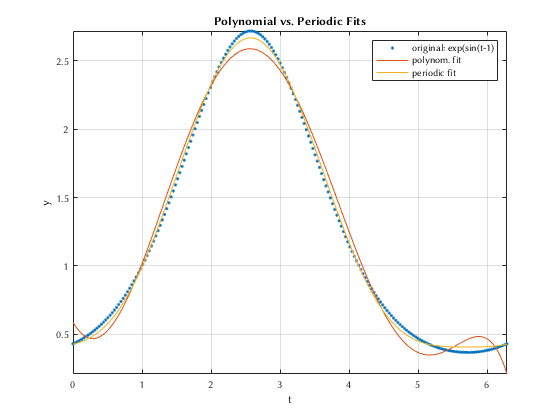

visMatrixNorms(A, 1);

$p = 2$: (not asked in the problem)

visMatrixNorms(A, 2);

ans =           1.17911555525399

$p=\infty$:

visMatrixNorms(A, Inf);

ans =          0.445661032186688

### Explore.

Modify the script/function even further so that it can handle any $p \in [1, \infty]$. MATLAB's `norm` function can calculate vector $p$-norm for any value $p$, but it can only calculate $\Vert A \Vert_p$ for $p = 1, 2, \infty$ and $\Vert A \Vert_F$ (Frobenius norm). So for $p$ other than $1, 2, \infty$, your program must only output the approximate $\Vert A \Vert_p$. 

## Functions Used

### Visualization of Matrix Norms

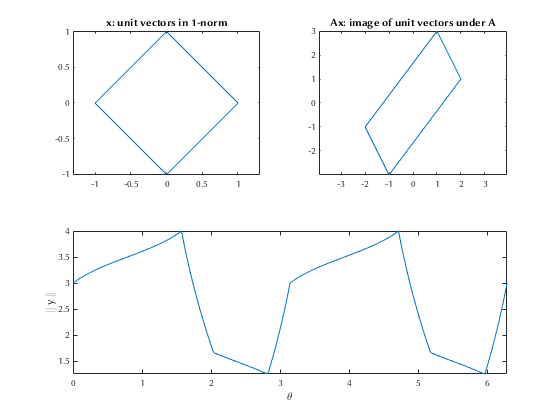

 p = 1
 approx. norm: 4.0000000000000000
 actual  norm: 4.0000000000000000


function normA = visMatrixNorms(A, p)
% VISMATRIXNORM visMatrixNorms(A, p)
% Generate plots of unit vectors (in p-norm) and their images under A.
% Also approximates the matrix p-norm of A according to the definition of
% induced norms.
%
% Input:
%   A      2-by-2 matrix
%   p      1, 2, or Inf
% Output:

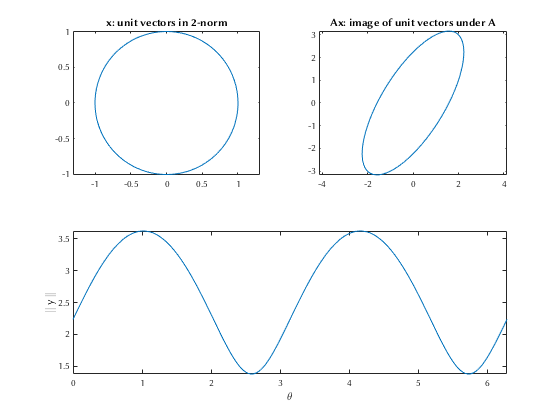

 p = 2
 approx. norm: 3.6179964204609893
 actual  norm: 3.6180339887498953


%  normA   matrix p-norm of A (approximation)
    if size(A,1)~=2 || size(A,2)~=2
        error('A must be a 2-by-2 matrix.')

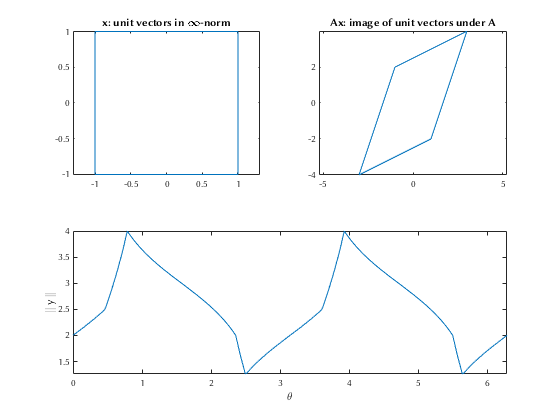

 p = Inf
 approx. norm: 3.9999999999999996
 actual  norm: 4.0000000000000000


    elseif p~=1 && p~=2 && p~=Inf
        error('p must be either 1, 2, or Inf.')
    end

    
    
    theta = linspace(0, 2*pi, 361);
    U = [cos(theta); sin(theta)];   % unit circle
    
    % Calculate p-norm of vectors on the unit circle
    if p == 1
        norm_U = sum( abs(U), 1 ); 
    elseif p == 2
        norm_U = sqrt( sum(abs(U).^2, 1) ); 
    else 
        norm_U = max( abs(U), [], 1 );
    end
    
    % Normalize to unit vectors in respective norm
    X = U ./ norm_U;
    
    % Calculate y's
    Y = A*X;
    
    % Calculate p-norm of y's
    if p == 1
        norm_Y = sum( abs(Y), 1 );
    elseif p == 2
        norm_Y = sqrt( sum(abs(Y).^2, 1) );
    else
        norm_Y = max( abs(Y), [], 1 );
    end
    normA = max(norm_Y);
    
    % Plotting routine
    clf
    subplot(2,2,1)
    plot(X(1,:), X(2,:)), axis equal
    
    if p ~= Inf
        str = sprintf('x: unit vectors in %g-norm', p);
    else
        str = sprintf('x: unit vectors in \\infty-norm', 'Interpreter', 'latex');
    end
    title(str)
    
    subplot(2,2,2)
    plot(Y(1,:), Y(2,:)), axis equal
    title('Ax: image of unit vectors under A')
    
    subplot(2,1,2)
    plot(theta, norm_Y), axis tight
    xlabel('\theta')
    ylabel('|| y ||')

    fprintf(' p = %g\n', p)
    fprintf(' approx. norm: %18.16f\n', normA)
    fprintf(' actual  norm: %18.16f\n', norm(A, p))
end